# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

file='tgas_model.xlsx';
model=CheckDataModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [Reference] are valid
INFO: cStatusLogger. Exergy values [TURB86] are valid
INFO: cStatusLogger. Exergy values [COMP86] are valid
INFO: cStatusLogger. Exergy values [PC78] are valid
INFO: cStatusLogger. Exergy values [T25] are valid
INFO: cStatusLogger. Exergy values [ECTR] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Resources Cost sample [STACK] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model tgas_model.xlsx is valid


#### Select the parameters

States=convertCharsToStrings(model.getStateNames);
State=convertStringsToChars(States(4));
Samples=convertCharsToStrings(model.getResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));

#### Compute Cost Analysis

res=ThermoeconomicAnalysis(model,'State',State, ...
    'CostTables','ALL','ResourceSample',ResourceSample);

#### Show Results

printResults(res);

Process Exergy Cost

  Id  Key       P*(kW)    Pe*(kW)    Pr*(kW)     F*(kW)     R*(kW)
-------------------------------------------------------------------
   1  COMB     38348.3    36914.0     1434.3    36914.0     1434.3
   2  COMP     18745.2    17891.2      854.1    18667.7       77.5
   3  GTRB     36779.4    35249.5     1529.9    36721.3       58.1
   4  HRSG     18802.3    18048.7      753.6    18802.3        0.0
   5  STCK      1569.9     1507.0       62.9     1569.9        0.0


Process Unit Exergy Cost

  Id  Key     kP*(J/J)  kPe*(J/J)  kPr*(J/J)   kF*(J/J)   kR*(J/J)     k(J/J)
------------------------------------------------------------------------------
   1  COMB      1.6227     1.5620     0.0607     1.0000     0.0607     1.5620
   2  COMP      1.9549     1.8658     0.0891     1.8112     0.0081     1.0749
   3  GTRB      1.8112     1.7358     0.0753     1.7186     0.0029     1.0522
   4  HRSG      2.6231     2.5180     0.1051     1.7186     0.0000     1.5263
   5  STCK  

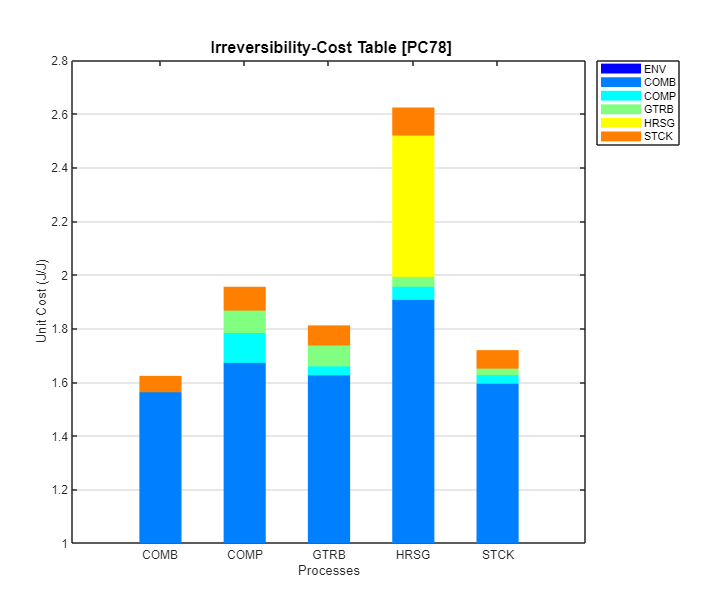

graphCost(res);